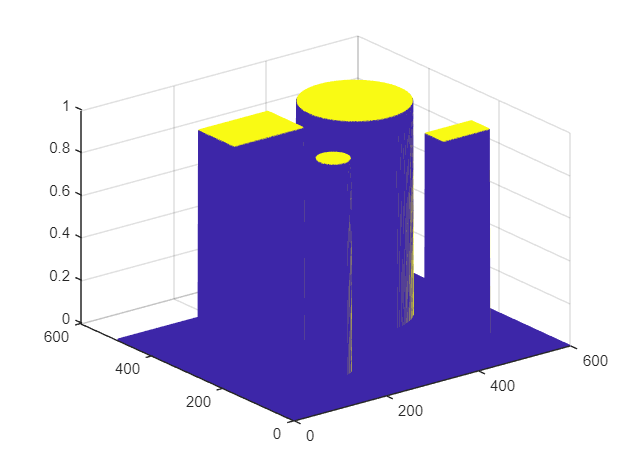

m =   Surface with properties:

       EdgeColor: 'flat'
       LineStyle: '-'
       FaceColor: [1 1 1]
    FaceLighting: 'none'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 … ]
           YData: [500×1 double]
           ZData: [500×600 double]
           CData: [500×600 double]

  Show all properties


nrows = 500;
ncols = 600;

obstacle = false(nrows,ncols);

[x, y] = meshgrid(1:ncols, 1:nrows);

obstacle(300:400, 100:250) = true; % rectangular obstacle
obstacle(100:150, 400:500) = true; % rectangular obstacle 

t = ((x-200).^2 + (y-150).^2 < 30^2) ; %circular obstacle
obstacle(t) = true;
t = ((x-400).^2 + (y-350).^2 < 100^2) ; %circular obstacle
obstacle(t) = true; %map every point where the obstacle lies as true.


m = mesh(obstacle);

% axis equal
obstacle;

d = bwdist(obstacle); %research on this 

d = 500×600 single matrix
  218.8058  218.0023  217.2004  216.4001  215.6015  214.8046  214.0093  213.2159  212.4241  211.6341  210.8459  210.0595  209.2749  208.4922  207.7113  206.9324  206.1553  205.3801  204.6069  203.8357  203.0665  202.2993  201.5341  200.7710  200.0100  199.2511  198.4943  197.7397  196.9873  196.2371  195.4891  194.7434  194.0000  193.2589  192.5201  191.7837  191.0497  190.3182  189.5890  188.8624  188.1382  187.4166  186.6976  185.9812  185.2674  184.5562  183.8478  183.1420  182.4335  181.7278
  218.2132  217.4075  216.6033  215.8008  215.0000  214.2008  213.4034  212.6076  211.8136  211.0213  210.2308  209.4421  208.6552  207.8701  207.0869  206.3056  205.5262  204.7486  203.9730  203.1994  202.4278  201.6581  200.8905  200.1250  199.3615  198.6001  197.8409  197.0837  196.3288  195.5761  194.8256  194.0773  193.3313  192.5876  191.8463  191.1073  190.3707  189.6365  188.9047  188.1754  187.4487  186.7244  186.0027  185.2836  184.5671  183.8532  183.1420  1

K = 100;
Rho = d/K +1;
d0 = 2;
Eta = 1000;
repulsive = (Eta/2)*((1./Rho-1/d0).^2);
repulsive(Rho > d0) = 0;
% figure;
% m = mesh(repulsive)
% m.FaceLighting = 'phong';
% axis equal;
% title ('Repulsive Potential');
% hold on
max(max(repulsive));

goal = [286, 229];
zeta = 1/1000 ;
attractive = zeta * ( (x- goal(1)).^2 + (y-goal(2)).^2);

attractive =   133.2090  132.6400  132.0730  131.5080  130.9450  130.3840  129.8250  129.2680  128.7130  128.1600  127.6090  127.0600  126.5130  125.9680  125.4250  124.8840  124.3450  123.8080  123.2730  122.7400  122.2090  121.6800  121.1530  120.6280  120.1050  119.5840  119.0650  118.5480  118.0330  117.5200  117.0090  116.5000  115.9930  115.4880  114.9850  114.4840  113.9850  113.4880  112.9930  112.5000  112.0090  111.5200  111.0330  110.5480  110.0650  109.5840  109.1050  108.6280  108.1530  107.6800
  132.7540  132.1850  131.6180  131.0530  130.4900  129.9290  129.3700  128.8130  128.2580  127.7050  127.1540  126.6050  126.0580  125.5130  124.9700  124.4290  123.8900  123.3530  122.8180  122.2850  121.7540  121.2250  120.6980  120.1730  119.6500  119.1290  118.6100  118.0930  117.5780  117.0650  116.5540  116.0450  115.5380  115.0330  114.5300  114.0290  113.5300  113.0330  112.5380  112.0450  111.5540  111.0650  110.5780  110.0930  109.6100  109.1290  108.6500  108.1730  107.

% figure;
% m = mesh(attractive);
% m.FaceLighting = 'phong';
% axis equal;
% title ('Attractive Potential');
max(max(attractive));

f = attractive + repulsive; 

f = 500×600 single matrix
  133.2090  132.6400  132.0730  131.5080  130.9450  130.3840  129.8250  129.2680  128.7130  128.1600  127.6090  127.0600  126.5130  125.9680  125.4250  124.8840  124.3450  123.8080  123.2730  122.7400  122.2090  121.6800  121.1530  120.6280  120.1050  119.5840  119.0650  118.5480  118.0330  117.5200  117.0090  116.5000  115.9930  115.4880  114.9850  114.4840  113.9850  113.4880  112.9930  112.5000  112.0090  111.5200  111.0330  110.5480  110.0650  109.5840  109.1050  108.6280  108.1530  107.6800
  132.7540  132.1850  131.6180  131.0530  130.4900  129.9290  129.3700  128.8130  128.2580  127.7050  127.1540  126.6050  126.0580  125.5130  124.9700  124.4290  123.8900  123.3530  122.8180  122.2850  121.7540  121.2250  120.6980  120.1730  119.6500  119.1290  118.6100  118.0930  117.5780  117.0650  116.5540  116.0450  115.5380  115.0330  114.5300  114.0290  113.5300  113.0330  112.5380  112.0450  111.5540  111.0650  110.5780  110.0930  109.6100  109.1290  108.6500  1

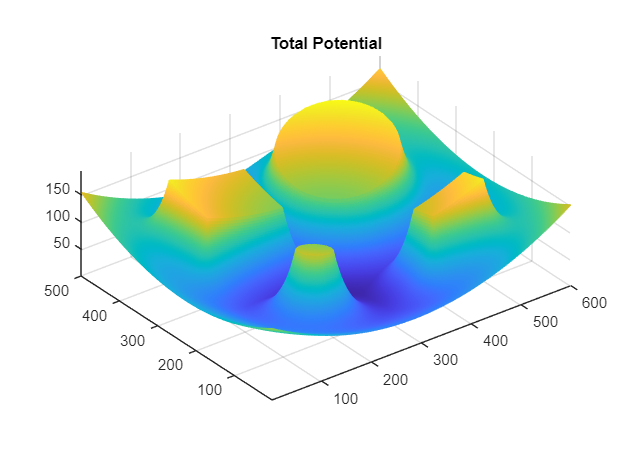

figure;
m = mesh(f);
% m.FaceLighting('phong');
axis equal;
title("Total Potential")

max(max(f));

start = [50, 350];
[gx, gy] = gradient(-f);

gx = 500×600 single matrix
    0.5690    0.5680    0.5660    0.5640    0.5620    0.5600    0.5580    0.5560    0.5540    0.5520    0.5500    0.5480    0.5460    0.5440    0.5420    0.5400    0.5380    0.5360    0.5340    0.5320    0.5300    0.5280    0.5260    0.5240    0.5220    0.5200    0.5180    0.5160    0.5140    0.5120    0.5100    0.5080    0.5060    0.5040    0.5020    0.5000    0.4980    0.4960    0.4940    0.4920    0.4900    0.4880    0.4860    0.4840    0.4820    0.4800    0.4780    0.4760    0.4740    0.4720
    0.5690    0.5680    0.5660    0.5640    0.5620    0.5600    0.5580    0.5560    0.5540    0.5520    0.5500    0.5480    0.5460    0.5440    0.5420    0.5400    0.5380    0.5360    0.5340    0.5320    0.5300    0.5280    0.5260    0.5240    0.5220    0.5200    0.5180    0.5160    0.5140    0.5120    0.5100    0.5080    0.5060    0.5040    0.5020    0.5000    0.4980    0.4960    0.4940    0.4920    0.4900    0.4880    0.4860    0.4840    0.4820    0.4800    0.4780  

gy = 500×600 single matrix
    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550    0.4550
    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540    0.4540  


route = start;
Point_on_route = start;
Speed = 3;
Tolerance = 1;
iterations =1000 ;

while(iterations >0)
    if(norm(goal - Point_on_route)<Tolerance)
        break;
    end
    delta_x = gx(floor(Point_on_route(2)), floor(Point_on_route(1)));
    delta_y = gy(floor(Point_on_route(2)), floor(Point_on_route(1)));

    delta = [delta_x, delta_y];
    %delta vector is both value and direction.

    delta_Direction_x = delta_x/norm(delta);
    delta_Direction_y = delta_y/norm(delta);
    
    new_route_x = Point_on_route(1) + Speed * delta_Direction_x;
    new_route_y = Point_on_route(2) + Speed * delta_Direction_y;
    
    Point_on_route = [new_route_x, new_route_y];

    route = [route; Point_on_route];
%     plot(new_route_x,new_route_y,'LineWidth',2,'MarkerSize',2);
% %     pause(0.1)
    iterations = iterations -1 ;
    %
end

%% Plot the energ surface.

figure;
m = mesh(f);
axis equal

%% Plot a ball to vishualize 

[sx, sy, sz] = sphere();

R = 10;
sx = R*sx;
sy = R*sy;
sz = R*sz +R;
% the lower half will not be vissible if added R

hold on;
p = mesh(sx,sy,sz);
%this will plot the ball at 0,0,0
p.FaceColor = 'red';
p.EdgeColor = 'none';
% p.FaceLighting = 'phong';
hold off;

hold on
plot(goal(1),goal(2),'g*','MarkerSize',25);
hold off

%Plot the ball at each point in route from start to goal
for i = 1:size(route,1)
    P = round(route(i,:));
    %P = [x,y]
    z = f(P(2),P(1)); 
    % z = f(x,y)

    %Draw the ball shifted to the new pos
    p.XData = sx + P(1);
    p.YData = sy + P(2);
    p.ZData = sz + f(P(2),P(1));

    drawnow;

    pause(0.05)
end

%% Quiver plot 
[gx, gy] = gradient(-f);
skip = 20 ;
figure ;

xidx = 1:skip:ncols;
yidx = 1:skip:nrows;

quiver(x(yidx,xidx),y(yidx,xidx),gx(yidx,xidx),gy(yidx,xidx),0.4);

axis([1 ncols 1 nrows]);

hold on ;

ps = plot(start(1), start(2), 'r.','MarkerSize',30);
pg = plot(goal(1),goal(2),'g.',MarkerSize=30);
pp3 = plot(route(:,1),route(:,2),'r','LineWidth',2);

